%homework 2 part 2
load('BZ.mat')
[m,n,k]=size(BZ_tensor); % x vs y vs time data
% for j=1:k
%     
%     B=BZ_tensor(:,:,j);
%     pcolor(B), shading interp, pause(0.2)
% end

%take snapshot of data and reshape
Z = reshape(BZ_tensor(1:50,1:50,1:200),[2500,200]);
[ub, sb, vb] = svd(Z,'econ');
w = diag(sb)/sum(diag(sb));
%plot(w,'o')
thresh = find(w>.001);
nn = length(thresh);

r = nn;
[Phi, Lambda] = DMD(Z(:,1:end-1),Z(:,2:end),r);
dt = 1;
t = 1:dt:400;
mu = diag(Lambda);
omega = log(mu)/dt;
u0 = Z(:,1);
y0 = Phi\u0; %psuedo inverse IC
u_modes = zeros(r,length(t));
for i = 1:length(t)
    u_modes(:,i) = (y0.*exp(omega*t(i)));
end
u_dmd = Phi*u_modes;


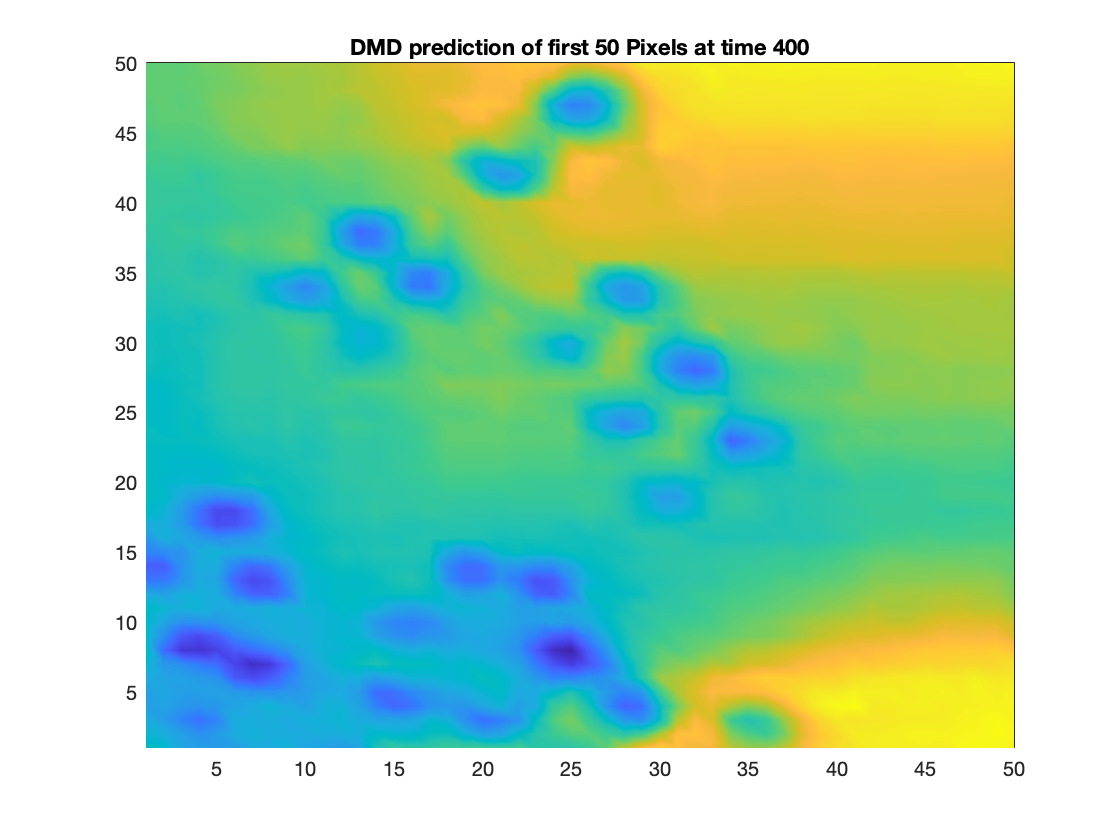

u_dmdp = reshape(real(u_dmd),[50,50,400]);
%for j = 1:400
figure(2)
    B = u_dmdp(:,:,201);
    pcolor(B), shading interp,    
    title('DMD prediction of first 50 Pixels at time 400')

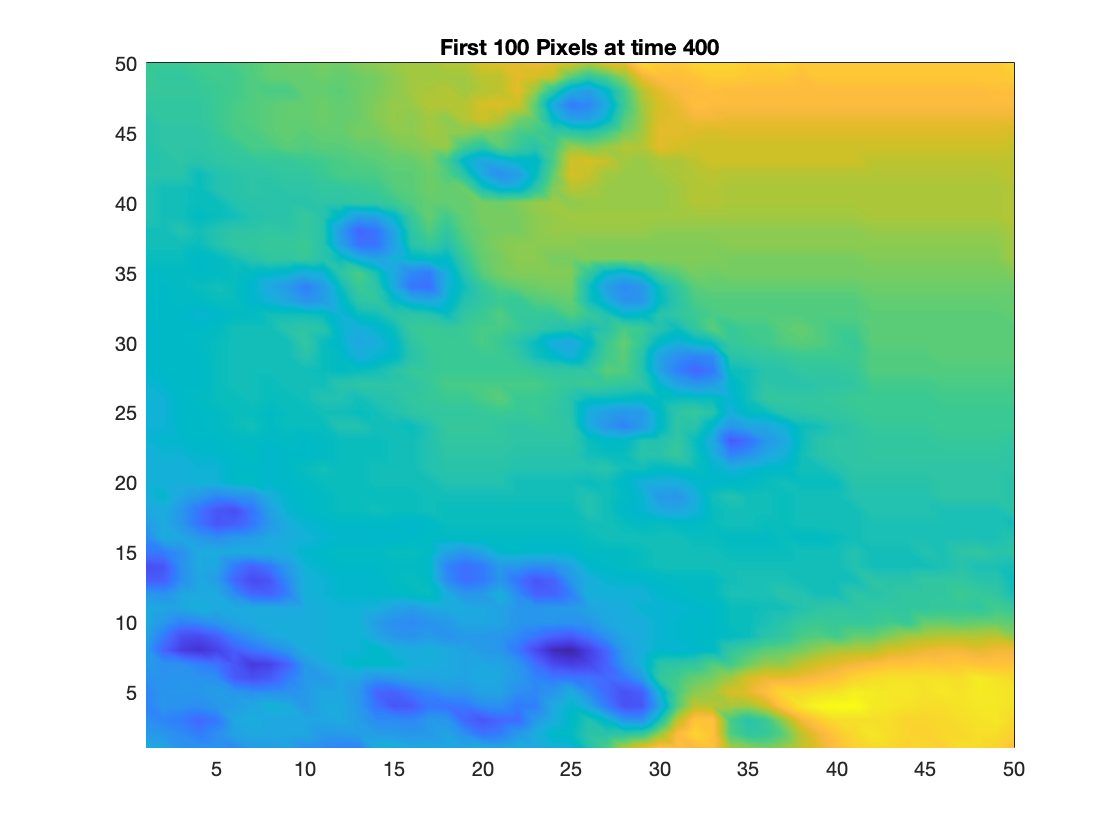

%end
figure(3)
pcolor(BZ_tensor(1:50,1:50,201)), shading interp
title('First 100 Pixels at time 400')

%build time delay
H =[];
Hp = [];
for i = 1:25
    H = [H;Z(:,i:(10+i))];
    Hp = [Hp;Z(:,(i+1):10+(i+1))];    
    end
[u,s1,v]= svd(H,'econ');
figure(3)
v = diag(s1)/sum(diag(s1));
thresh2 = find(v>.001);
mm = length(thresh2);

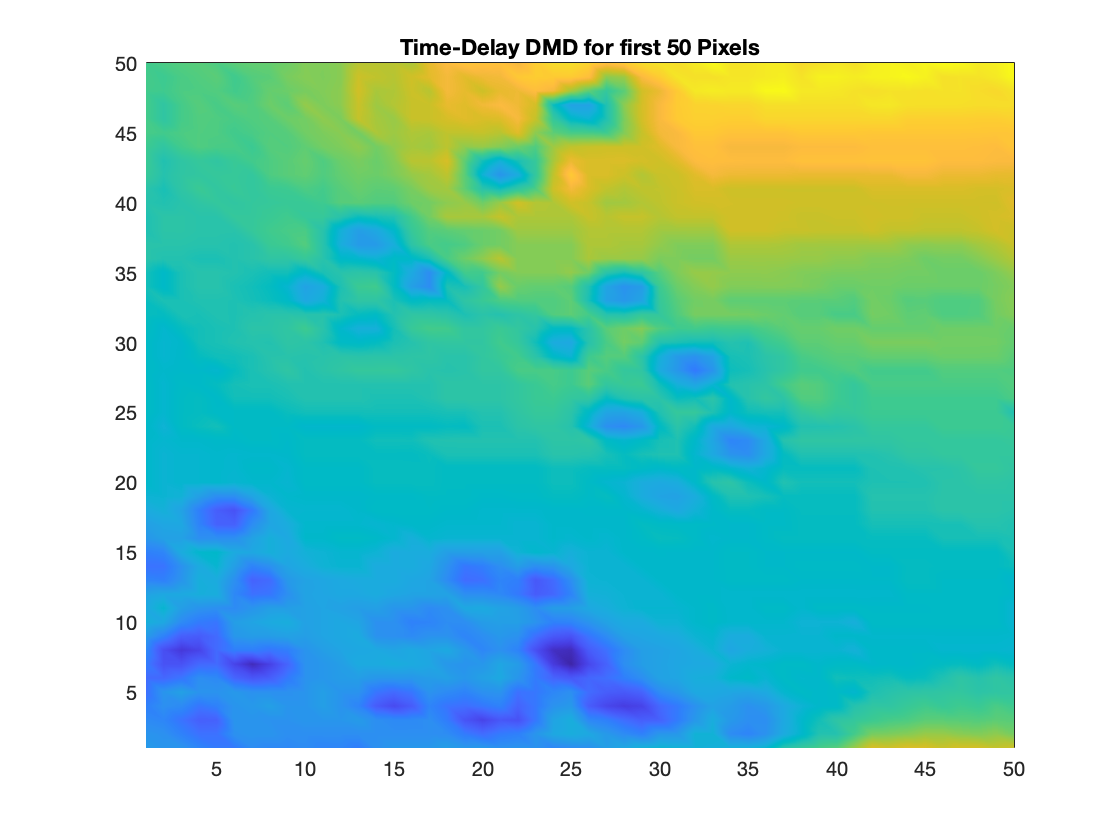

r = 3;

[Phih,Lambdah] = DMD(H,Hp,r);
t = 1:400;
muh = diag(Lambdah);
omegah = log(muh)/dt;
u0h = H(:,1);
y0h = Phih\u0h; %psuedo inverse IC
u_modes2 = zeros(r,length(t));
for i = 1:length(t)
    u_modes2(:,i) = (y0h.*exp(omegah*t(i)));
end
u_dmd2 = Phih*u_modes2;
u_dmd2p = reshape(real(u_dmd2(1:2500,:)),[50,50,400]);
figure(4)
pcolor(u_dmd2p(:,:,201)), shading interp
title('Time-Delay DMD for first 50 Pixels')

% %KL divergence
% f = hist(Z);
% g1 =hist(u_dmd(:,1:200));
% g2 = hist(u_dmd2(1:2500,1:200));
% 
% f = f/trapz(f) + 0.01;
% g1 = g1/trapz(g1)+ 0.01;
% g2 = g2/trapz(g2)+ 0.01;
% 
% int1 = f.*log(f./g1);
% int2 = f.*log(f./g2);
% 
% I1 = trapz(int1)

I1 = 0.0080

% I2 = trapz(int2)

I2 = 0.1945

norm(abs(Z - u_dmd(:,1:200)))/norm(Z)

ans = 0.0244

norm(abs(Z -u_dmd2(1:2500,1:200)))/norm(Z)

ans = 0.2337

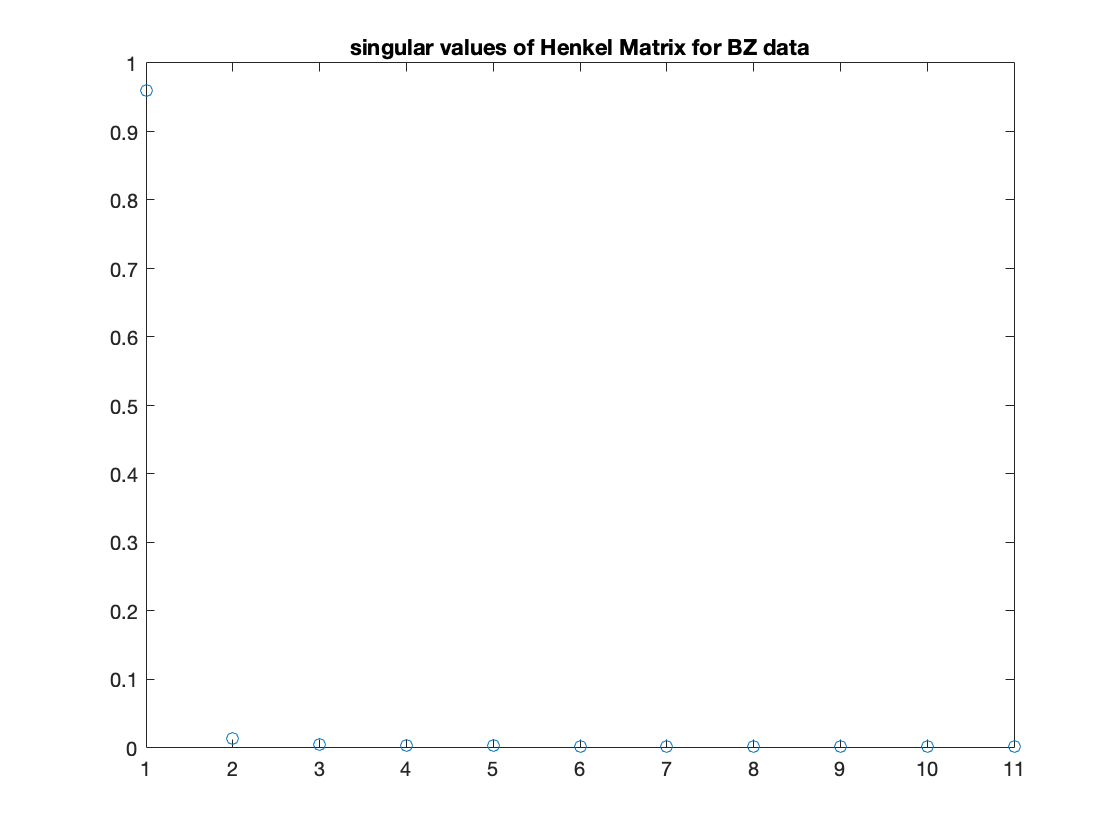

plot(v,'o'), title('singular values of Henkel Matrix for BZ data')